%Simulation of Instantaneous Centre of Rotation of Brace

%User provided parameters
mass = 56.7; %kilograms
height = 1.73; %metres
thighdiameter = 0.1; %metres
calfdiameter = 0.08; %metres

%Thigh/Calf Length from Winters Segment Model
thighlength = (0.530 - 0.285)*height;
calflength = (0.285 - 0.0039)*height;


%Instantiate Objects
S = SuperiorLink;
A = AnteriorLink;
In = InferiorLink;
P = PosteriorLink;
T1 = TorsionalSpring;
T2 = TorsionalSpring;
ZF = Z_forces;
VT = Velcro;
VC = Velcro;
Blt = Bolt;
Brng = Bearing;
SF = SafetyFactor;

disp("Link and Spring Object Instantiated.");

Link and Spring Object Instantiated.



%Initialize dimensions based on Mass and Height
Init_System(mass, height, S, In, P, A, T1, T2,VT,VC,Blt,Brng, thighdiameter, calfdiameter);

%Initialize Torsional Springs:
verticaloffset = GetInitKinematics(S, In, A, P, T1, T2);
T1 = initSpring(T1, mass, S, A);
T2 = initSpring(T2, mass, In, P);

%Parse Winters Data
WinterData = Parse_Winter_Data("Winter_Appendix_data_fixed.xlsx");
kinematicsdata = WinterData{3};

startframe = 28; %HCR
endframe = 96; %Just Before HCR

superiordata = zeros(endframe - startframe + 1, 9);
anteriordata = zeros(endframe - startframe + 1, 9);
inferiordata = zeros(endframe - startframe + 1, 9);
posteriordata = zeros(endframe - startframe + 1, 9);
spring1data = zeros(1 ,endframe - startframe + 1);
spring2data = zeros(1 ,endframe - startframe + 1);
totalextensivetorque = zeros(1 ,endframe - startframe + 1);
totalPE = zeros(1 ,endframe - startframe + 1);
framess = zeros(1 ,endframe - startframe + 1);
NA1 = zeros(1 ,endframe - startframe + 1);
NA2 = zeros(1 ,endframe - startframe + 1);

for i=startframe:endframe
    %Obtain biological kinematics of calf and thigh.
kincalf = [kinematicsdata(i,16), kinematicsdata(i,17), kinematicsdata(i,18), 0, 0, 0; 
           kinematicsdata(i,19), kinematicsdata(i,20), kinematicsdata(i,21), 0, 0, 0;
           0, 0, 0, kinematicsdata(i,13), kinematicsdata(i,14), kinematicsdata(i,15);];
       
kinthigh = [kinematicsdata(i,26), kinematicsdata(i,27), kinematicsdata(i,28), 0, 0, 0; 
           kinematicsdata(i,29), kinematicsdata(i,30), kinematicsdata(i,31), 0, 0, 0;
           0, 0, 0, kinematicsdata(i,23), kinematicsdata(i,24), kinematicsdata(i,25);];
       
%calculate kinematics
Kinematic_Modelling(S,In,P,A,kinthigh,kincalf, thighlength, calflength, T1, T2, verticaloffset);


dataindex = i - startframe + 1;
superiordata(dataindex, 1) = S.com_abs(1);
superiordata(dataindex, 2) = S.com_abs(2);
superiordata(dataindex, 3) = S.v(1);
superiordata(dataindex, 4) = S.v(2);
superiordata(dataindex, 5) = S.a(1);
superiordata(dataindex, 6) = S.a(2);
superiordata(dataindex, 7) = S.theta;
superiordata(dataindex, 8) = S.omega(3);
superiordata(dataindex, 9) = S.alpha(3);

anteriordata(dataindex, 1) = A.com_abs(1);
anteriordata(dataindex, 2) = A.com_abs(2);
anteriordata(dataindex, 3) = A.v(1);
anteriordata(dataindex, 4) = A.v(2);
anteriordata(dataindex, 5) = A.a(1);
anteriordata(dataindex, 6) = A.a(2);
anteriordata(dataindex, 7) = A.theta;
anteriordata(dataindex, 8) = A.omega(3);
anteriordata(dataindex, 9) = A.alpha(3);

inferiordata(dataindex, 1) = In.com_abs(1);
inferiordata(dataindex, 2) = In.com_abs(2);
inferiordata(dataindex, 3) = In.v(1);
inferiordata(dataindex, 4) = In.v(2);
inferiordata(dataindex, 5) = In.a(1);
inferiordata(dataindex, 6) = In.a(2);
inferiordata(dataindex, 7) = In.theta;
inferiordata(dataindex, 8) = In.omega(3);
inferiordata(dataindex, 9) = In.alpha(3);

posteriordata(dataindex, 1) = P.com_abs(1);
posteriordata(dataindex, 2) = P.com_abs(2);
posteriordata(dataindex, 3) = P.v(1);
posteriordata(dataindex, 4) = P.v(2);
posteriordata(dataindex, 5) = P.a(1);
posteriordata(dataindex, 6) = P.a(2);
posteriordata(dataindex, 7) = P.theta;
posteriordata(dataindex, 8) = P.omega(3);
posteriordata(dataindex, 9) = P.alpha(3);

%calculate forces
% Kinetic_Saggital(S,In,P,A,T1,T2);

[NA1(dataindex), NA2(dataindex)] = GetSpringAngles(S, A, In, P);
T1.theta = NA1(dataindex);
T2.theta = NA2(dataindex);


spring1data(dataindex) = T1.theta;
spring2data(dataindex) = T2.theta;

% totalextensivetorque(dataindex) = 2*(abs(T1.Torque(3) + T2.Torque(3)));
totalPE(dataindex) = T1.K*(T1.theta-T1.theta0)^2 + T2.K*(T2.theta-T2.theta0)^2;

framess(dataindex) = kinematicsdata(i, 1);


percentage = ((i - startframe + 1)/(endframe - startframe + 1)) * 100;
disp(percentage + "% completed.");
    
end

1.4493% completed.
2.8986% completed.
4.3478% completed.
5.7971% completed.
7.2464% completed.
8.6957% completed.
10.1449% completed.
11.5942% completed.
13.0435% completed.
14.4928% completed.
15.942% completed.
17.3913% completed.
18.8406% completed.
20.2899% completed.
21.7391% completed.
23.1884% completed.
24.6377% completed.
26.087% completed.
27.5362% completed.
28.9855% completed.
30.4348% completed.
31.8841% completed.
33.3333% completed.
34.7826% completed.
36.2319% completed.
37.6812% completed.
39.1304% completed.
40.5797% completed.
42.029% completed.
43.4783% completed.
44.9275% completed.
46.3768% completed.
47.8261% completed.
49.2754% completed.
50.7246% completed.
52.1739% completed.
53.6232% completed.
55.0725% completed.
56.5217% completed.
57.971% completed.
59.4203% completed.
60.8696% completed.
62.3188% completed.
63.7681% completed.
65.2174% completed.
66.6667% completed.
68.1159% completed.
69.5652% completed.
71.0145% completed.
72.4638% completed.
73.913% co


%get torque about centre of rotation or close by
%verify kinematics by specific frames, and by ranges of motion over gait
%cycle
%normalize grfs by mass, then recalculate.

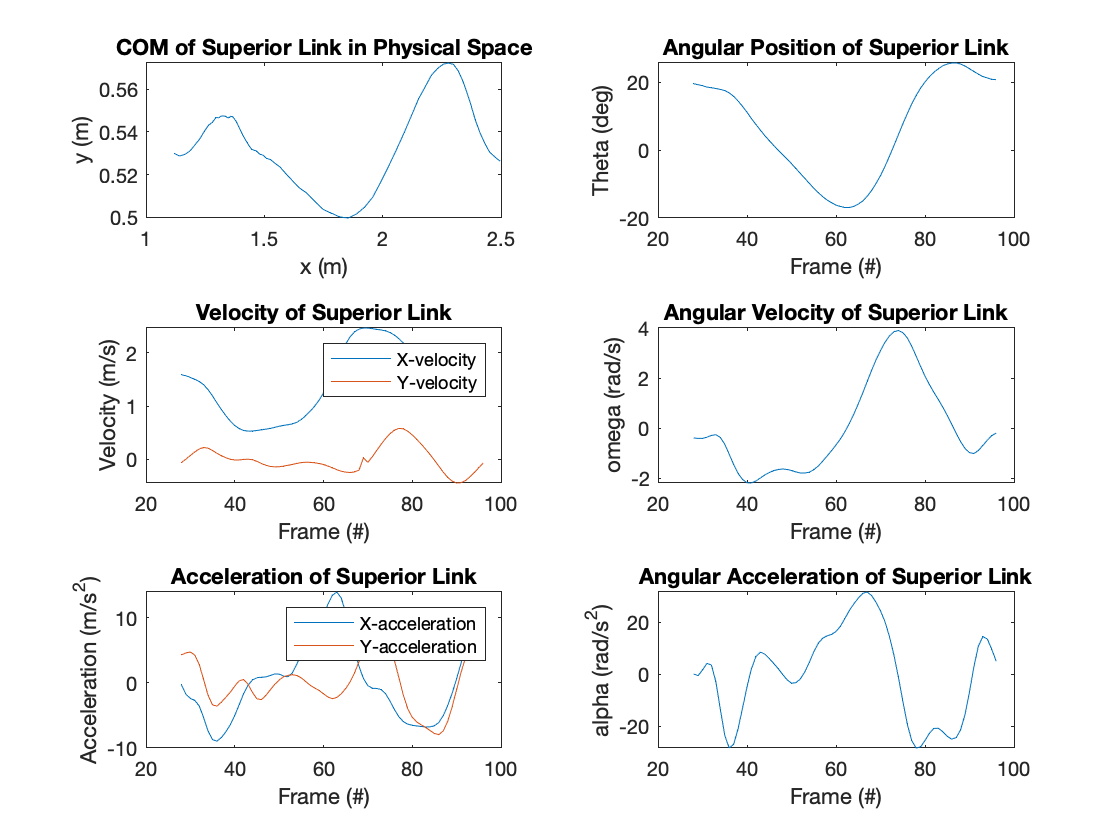

%Plots  

tiledlayout(3,2);
nexttile;
plot(superiordata(:, 1), superiordata(:, 2));
title("COM of Superior Link in Physical Space");
xlabel("x (m)");
ylabel("y (m)");

nexttile;
plot(framess, superiordata(:, 7));
title("Angular Position of Superior Link");
xlabel("Frame (#)");
ylabel("Theta (deg)");

nexttile;
plot(framess, superiordata(:, 3), framess, superiordata(:, 4));
title("Velocity of Superior Link");
xlabel("Frame (#)");
ylabel("Velocity (m/s)");
legend("X-velocity", "Y-velocity");

nexttile;
plot(framess, superiordata(:, 8));
title("Angular Velocity of Superior Link");
xlabel("Frame (#)");
ylabel("omega (rad/s)");

nexttile;
plot(framess, superiordata(:, 5), framess, superiordata(:, 6));
title("Acceleration of Superior Link");
xlabel("Frame (#)");
ylabel("Acceleration (m/s^2)");
legend("X-acceleration", "Y-acceleration");

nexttile;
plot(framess, superiordata(:, 9));
title("Angular Acceleration of Superior Link");
xlabel("Frame (#)");
ylabel("alpha (rad/s^2)");

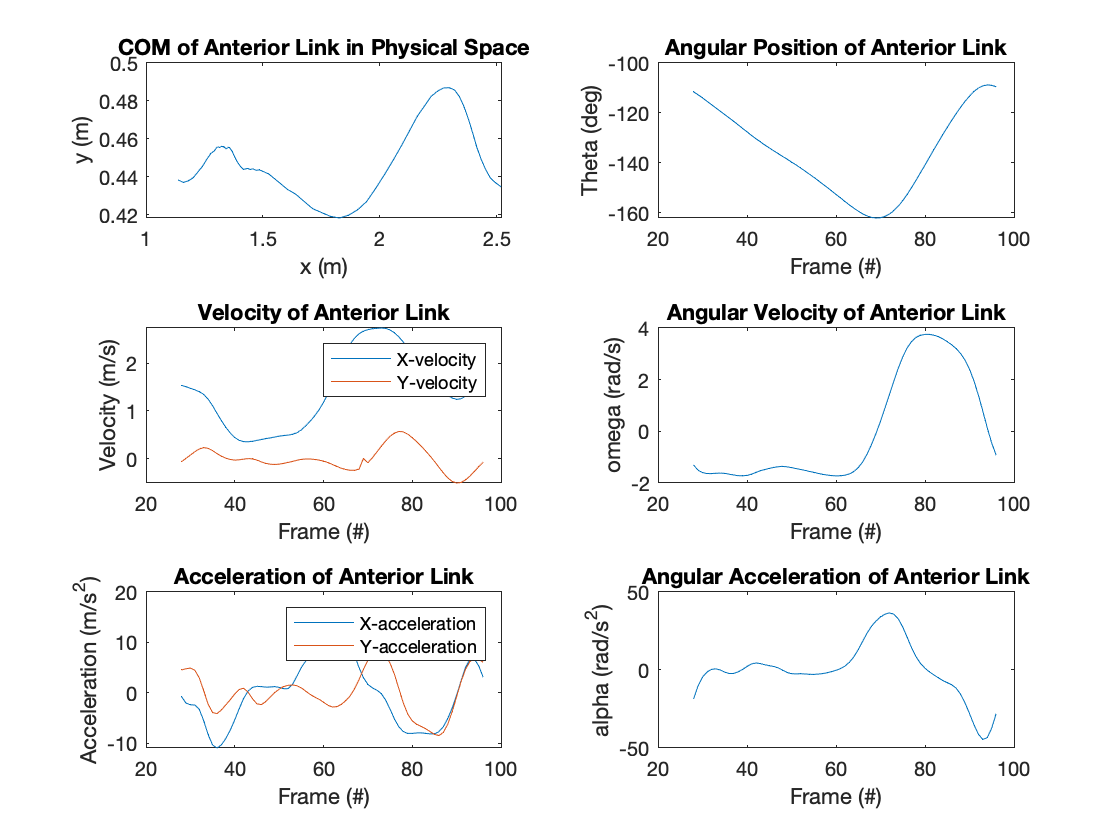

tiledlayout(3,2);
nexttile;
plot(anteriordata(:, 1), anteriordata(:, 2));
title("COM of Anterior Link in Physical Space");
xlabel("x (m)");
ylabel("y (m)");

nexttile;
plot(framess, anteriordata(:, 7));
title("Angular Position of Anterior Link");
xlabel("Frame (#)");
ylabel("Theta (deg)");

nexttile;
plot(framess, anteriordata(:, 3), framess, anteriordata(:, 4));
title("Velocity of Anterior Link");
xlabel("Frame (#)");
ylabel("Velocity (m/s)");
legend("X-velocity", "Y-velocity");

nexttile;
plot(framess, anteriordata(:, 8));
title("Angular Velocity of Anterior Link");
xlabel("Frame (#)");
ylabel("omega (rad/s)");

nexttile;
plot(framess, anteriordata(:, 5), framess, anteriordata(:, 6));
title("Acceleration of Anterior Link");
xlabel("Frame (#)");
ylabel("Acceleration (m/s^2)");
legend("X-acceleration", "Y-acceleration");

nexttile;
plot(framess, anteriordata(:, 9));
title("Angular Acceleration of Anterior Link");
xlabel("Frame (#)");
ylabel("alpha (rad/s^2)");

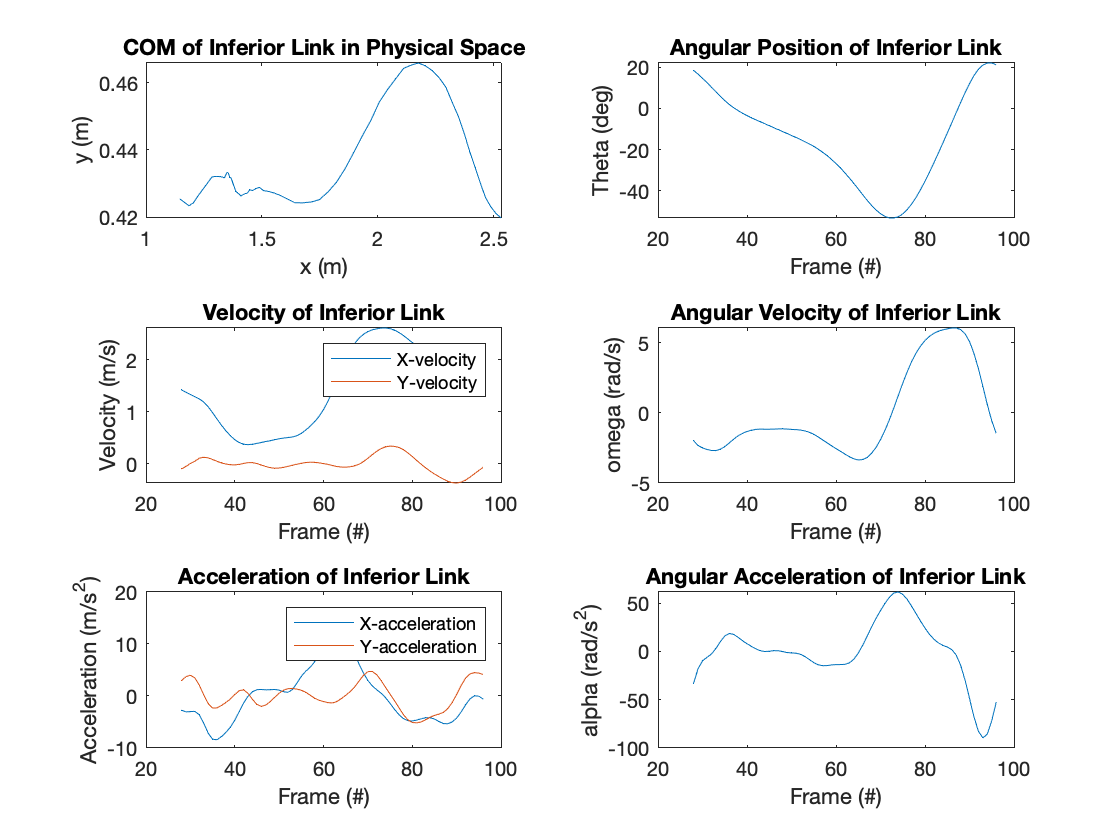

tiledlayout(3,2);
nexttile;
plot(inferiordata(:, 1), inferiordata(:, 2));
title("COM of Inferior Link in Physical Space");
xlabel("x (m)");
ylabel("y (m)");

nexttile;
plot(framess, inferiordata(:, 7));
title("Angular Position of Inferior Link");
xlabel("Frame (#)");
ylabel("Theta (deg)");

nexttile;
plot(framess, inferiordata(:, 3), framess, inferiordata(:, 4));
title("Velocity of Inferior Link");
xlabel("Frame (#)");
ylabel("Velocity (m/s)");
legend("X-velocity", "Y-velocity");

nexttile;
plot(framess, inferiordata(:, 8));
title("Angular Velocity of Inferior Link");
xlabel("Frame (#)");
ylabel("omega (rad/s)");

nexttile;
plot(framess, inferiordata(:, 5), framess, inferiordata(:, 6));
title("Acceleration of Inferior Link");
xlabel("Frame (#)");
ylabel("Acceleration (m/s^2)");
legend("X-acceleration", "Y-acceleration");

nexttile;
plot(framess, inferiordata(:, 9));
title("Angular Acceleration of Inferior Link");
xlabel("Frame (#)");
ylabel("alpha (rad/s^2)");

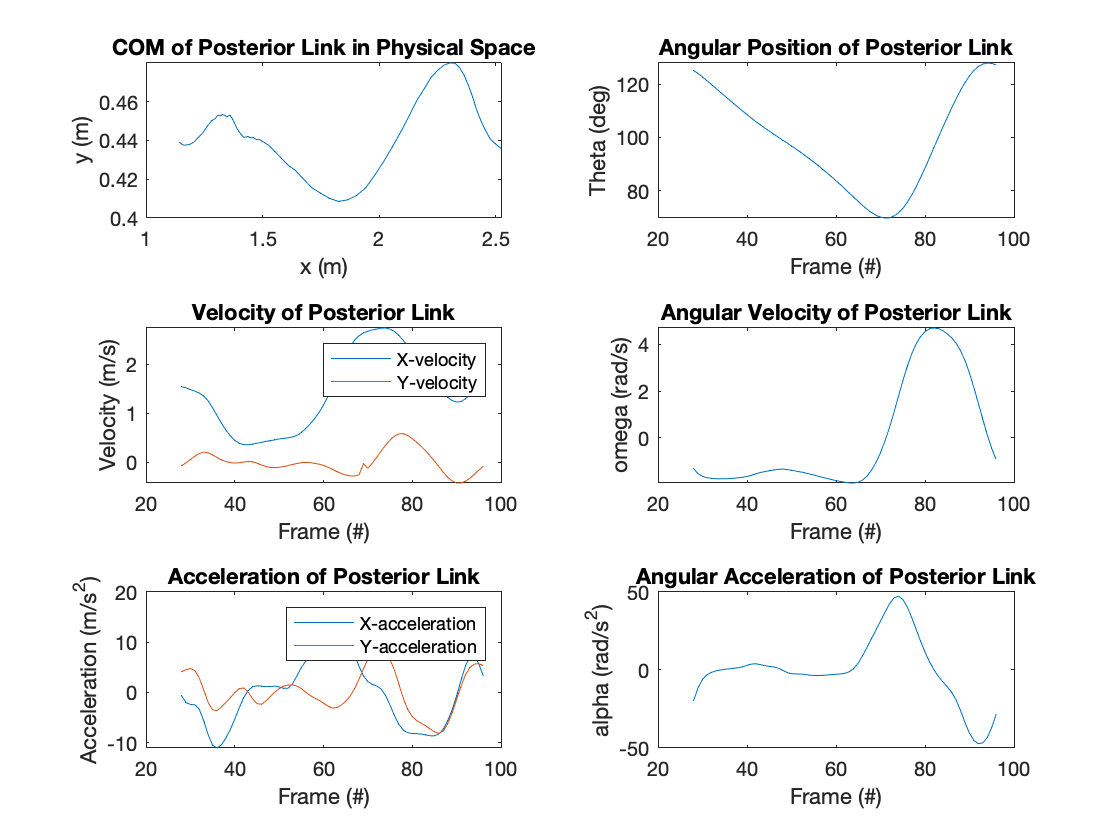

tiledlayout(3,2);
nexttile;
plot(posteriordata(:, 1), posteriordata(:, 2));
title("COM of Posterior Link in Physical Space");
xlabel("x (m)");
ylabel("y (m)");

nexttile;
plot(framess, posteriordata(:, 7));
title("Angular Position of Posterior Link");
xlabel("Frame (#)");
ylabel("Theta (deg)");

nexttile;
plot(framess, posteriordata(:, 3), framess, posteriordata(:, 4));
title("Velocity of Posterior Link");
xlabel("Frame (#)");
ylabel("Velocity (m/s)");
legend("X-velocity", "Y-velocity");

nexttile;
plot(framess, posteriordata(:, 8));
title("Angular Velocity of Posterior Link");
xlabel("Frame (#)");
ylabel("omega (rad/s)");

nexttile;
plot(framess, posteriordata(:, 5), framess, posteriordata(:, 6));
title("Acceleration of Posterior Link");
xlabel("Frame (#)");
ylabel("Acceleration (m/s^2)");
legend("X-acceleration", "Y-acceleration");

nexttile;
plot(framess, posteriordata(:, 9));
title("Angular Acceleration of Posterior Link");
xlabel("Frame (#)");
ylabel("alpha (rad/s^2)");

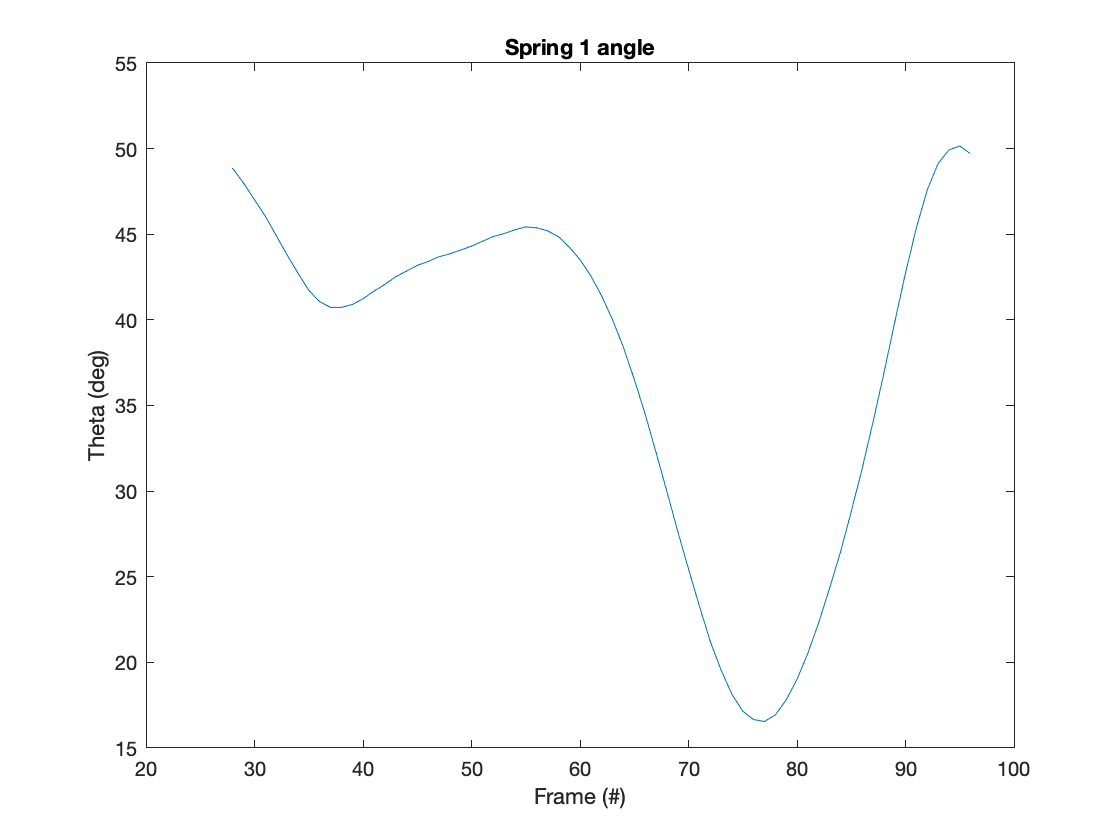

figure();
plot(framess, spring1data);
title("Spring 1 angle");
xlabel("Frame (#)");
ylabel("Theta (deg)")

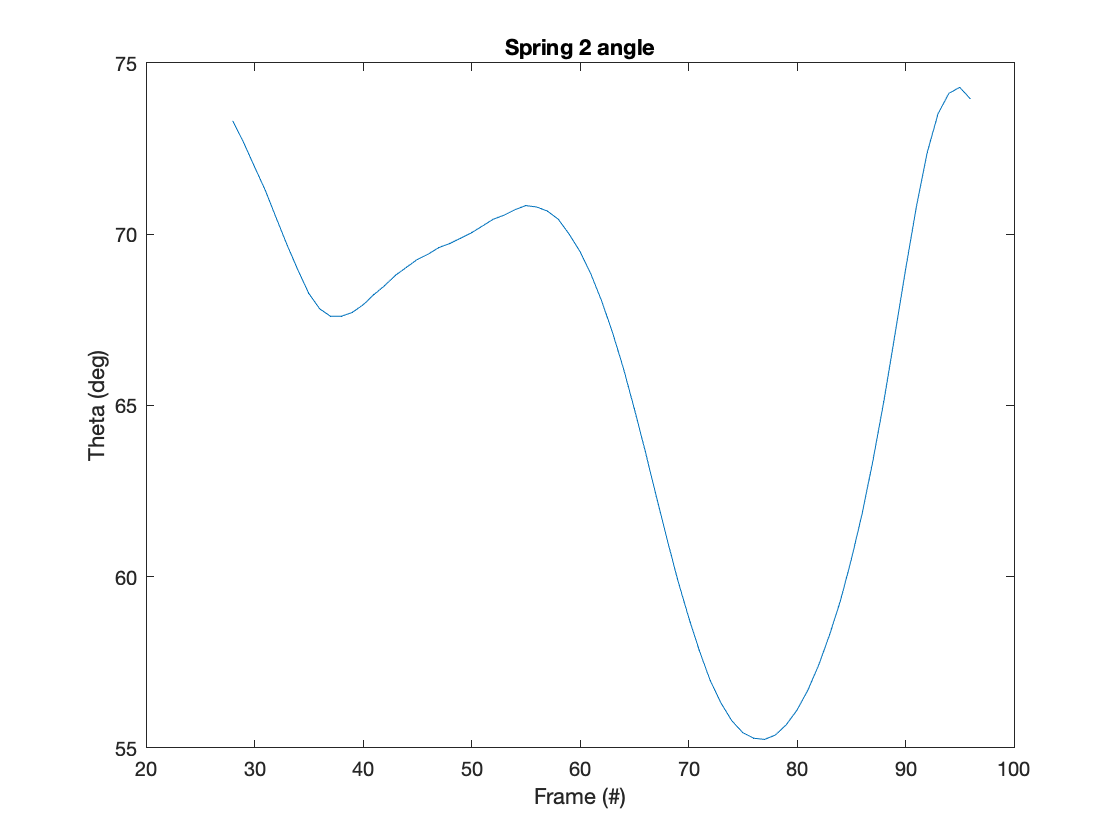

figure();
plot(framess, spring2data);
title("Spring 2 angle");
xlabel("Frame (#)");
ylabel("Theta (deg)")